graphs = init_population(15, 150);
graphs

graphs = 1×150 cell 数组
    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {

[allFronts, ~] = non_dominated_sorting(graphs);
multiFitValues = multi_obj_fitness(graphs);
f1 = ones(1, 150)./multiFitValues{1};
f2 = ones(1, 150)./multiFitValues{2};
f3 = ones(1, 150)./multiFitValues{3};
set(gcf,'Position',[100 100 260 220]);

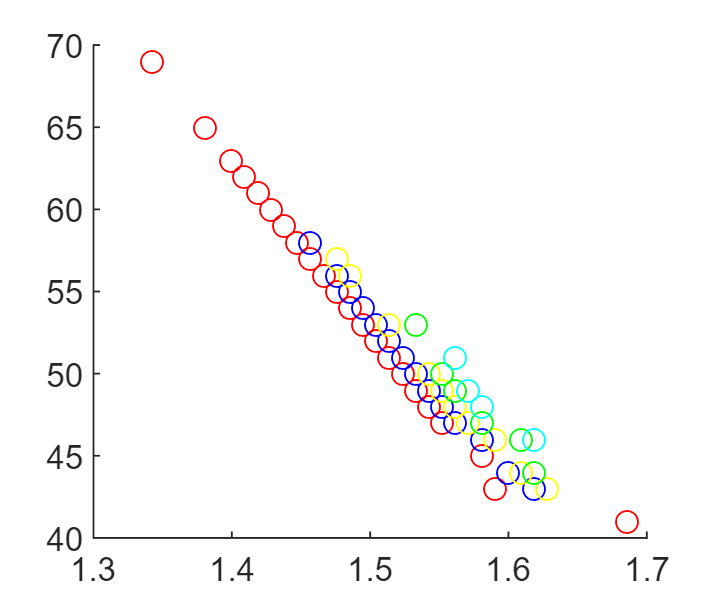

hold on
plot(f1(allFronts(1).front), f3(allFronts(1).front), 'ro');
plot(f1(allFronts(2).front), f3(allFronts(2).front), 'bo');
plot(f1(allFronts(3).front), f3(allFronts(3).front), 'yo');
plot(f1(allFronts(4).front), f3(allFronts(4).front), 'go');
plot(f1(allFronts(5).front), f3(allFronts(5).front), 'co');
hold off

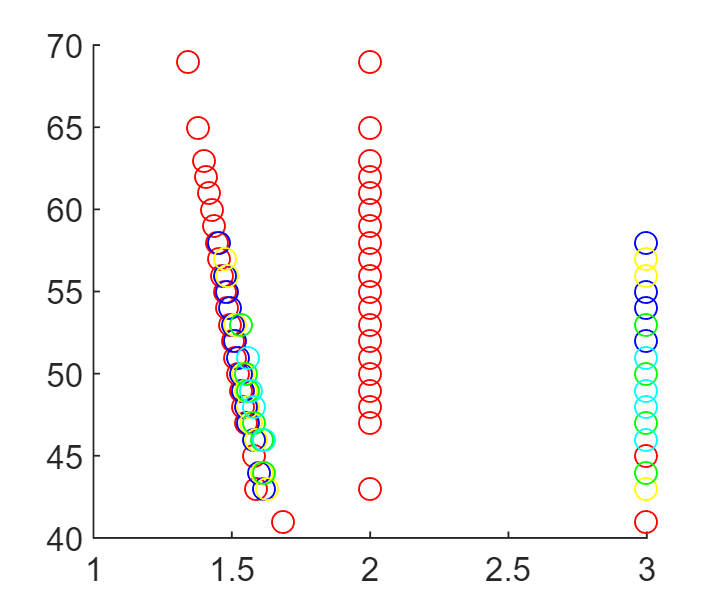

hold on
plot(f2(allFronts(1).front), f3(allFronts(1).front), 'ro');
plot(f2(allFronts(2).front), f3(allFronts(2).front), 'bo');
plot(f2(allFronts(3).front), f3(allFronts(3).front), 'yo');
plot(f2(allFronts(4).front), f3(allFronts(4).front), 'go');
plot(f2(allFronts(5).front), f3(allFronts(5).front), 'co');
hold off

[allFronts, ~] = non_dominated_sorting(graphs);
fitValues = multi_obj_fitness(graphs);
set(gcf,'Position',[100 100 260 220]);
plot(fitValues{1}(allFronts(1).front), fitValues{2}(allFronts(1).front), 'bo');
plot(fitValues{1}(allFronts(2).front), fitValues{2}(allFronts(2).front), 'go');
plot(fitValues{1}(allFronts(3).front), fitValues{2}(allFronts(3).front), 'ko');
plot(fitValues{1}(allFronts(4).front), fitValues{2}(allFronts(4).front), 'ro');

[bestGraph, bestFit] = EA(15, 0.4, 0.4)

popFitValues =     4.0952    3.9048    3.6381    3.3619    3.2762    3.2190    3.2000    3.2000    3.2000    3.1905    3.1619    3.0857    3.0762    3.0476    3.0381    3.0190    2.9143    2.9143    2.7238    2.6000    2.5714    2.5619    2.4952    2.4952    2.4857    2.4476    2.4190    2.3714    2.3429    2.1714    2.1619    2.1429    2.1333    2.1333    2.1238    2.0952    2.0952    2.0857    2.0667    2.0667    2.0476    2.0381    2.0190    2.0190    1.9905    1.9333    1.8952    1.8952    1.8857    1.8857


popFitValues =     5.9714    4.9619    4.5810    4.1143    4.0952    4.0857    4.0286    4.0286    3.9810    3.9238    3.9048    3.8571    3.8190    3.6667    3.6667    3.6381    3.5048    3.4000    3.3619    3.3524    3.3524    3.3333    3.2762    3.2571    3.2476    3.2476    3.2286    3.2190    3.2190    3.2190    3.2000    3.2000    3.2000    3.2000    3.1905    3.1810    3.1619    3.1238    3.1143    3.1143    3.0857    3.0762    3.0762    3.0667    3.0571    3.0571    3.0476    3.0381    3.0190    2.9143


popFitValues =     5.9714    5.9333    5.9238    5.8667    5.8476    5.8476    4.9714    4.9619    4.7619    4.6952    4.5810    4.1619    4.1524    4.1143    4.1143    4.1143    4.0952    4.0857    4.0762    4.0571    4.0571    4.0381    4.0286    4.0286    4.0286    4.0190    4.0095    4.0095    3.9810    3.9810    3.9810    3.9524    3.9524    3.9238    3.9238    3.9048    3.8952    3.8667    3.8571    3.8190    3.8190    3.8190    3.7905    3.7810    3.7619    3.7619    3.7333    3.6952    3.6667    3.6667


popFitValues =     6.6381    5.9714    5.9429    5.9333    5.9333    5.9238    5.8667    5.8476    5.8476    5.8476    5.7905    5.7905    5.6190    5.6190    5.2286    5.2095    5.1524    5.1143    4.9714    4.9619    4.8667    4.8476    4.7619    4.6952    4.6952    4.6476    4.5905    4.5810    4.5524    4.5429    4.5143    4.2571    4.2095    4.1810    4.1619    4.1619    4.1524    4.1333    4.1333    4.1238    4.1143    4.1143    4.1143    4.1048    4.0952    4.0952    4.0857    4.0857    4.0762    4.0667


popFitValues =     7.2762    7.2571    6.7810    6.6381    6.6381    6.6381    6.3333    6.1714    6.1048    6.0381    5.9714    5.9429    5.9333    5.9333    5.9238    5.9048    5.8667    5.8476    5.8476    5.8476    5.8095    5.8095    5.7905    5.7905    5.7905    5.7905    5.7714    5.7333    5.6571    5.6190    5.6190    5.4000    5.3810    5.3048    5.2667    5.2286    5.2286    5.2286    5.2095    5.1524    5.1429    5.1143    5.0952    5.0762    5.0762    5.0190    5.0190    4.9714    4.9619    4.8667


popFitValues =     7.5714    7.2762    7.2571    6.9143    6.8095    6.7810    6.7810    6.7333    6.6571    6.6381    6.6381    6.6381    6.6381    6.6381    6.6381    6.5238    6.4286    6.3333    6.2381    6.1714    6.1143    6.1048    6.1048    6.0952    6.0571    6.0381    6.0381    6.0000    5.9714    5.9429    5.9333    5.9333    5.9333    5.9238    5.9048    5.8667    5.8667    5.8667    5.8667    5.8476    5.8476    5.8476    5.8476    5.8476    5.8476    5.8476    5.8095    5.8095    5.8095    5.8095


popFitValues =     8.0476    8.0476    7.5714    7.4095    7.3333    7.2762    7.2762    7.2571    7.2571    7.2571    7.2571    6.9143    6.8095    6.7810    6.7810    6.7524    6.7333    6.7143    6.7143    6.6571    6.6571    6.6571    6.6381    6.6381    6.6381    6.6381    6.6381    6.6381    6.6381    6.6381    6.5619    6.5238    6.5238    6.4762    6.4667    6.4286    6.4286    6.3333    6.3333    6.2381    6.1810    6.1714    6.1524    6.1429    6.1429    6.1238    6.1143    6.1143    6.1048    6.1048


popFitValues =     8.1238    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    7.8762    7.5714    7.4095    7.3905    7.3333    7.3333    7.2952    7.2762    7.2762    7.2762    7.2762    7.2571    7.2571    7.2571    7.2571    7.2571    7.2571    7.2571    7.2571    7.2571    6.9143    6.8095    6.8000    6.7810    6.7810    6.7810    6.7524    6.7333    6.7143    6.7143    6.7048    6.6857    6.6857    6.6571    6.6571    6.6571    6.6381    6.6381    6.6381    6.6381    6.6381    6.6381    6.6381


popFitValues =     8.6667    8.1238    8.0667    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    7.8762    7.8762    7.5714    7.5619    7.4286    7.4095    7.3905    7.3333    7.3333    7.3333    7.3048    7.2952    7.2762    7.2762    7.2762    7.2762    7.2762    7.2571    7.2571    7.2571    7.2571    7.2571    7.2571    7.2571    7.2571    7.2571    7.2571    7.2571    7.2571    7.2571    7.2571    7.1810    7.1810    7.1619    7.1619


popFitValues =     8.6667    8.6667    8.1238    8.0667    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    7.8762    7.8762    7.8762    7.6286    7.6095    7.5714    7.5619    7.4286    7.4286    7.4286    7.4095    7.3905    7.3905    7.3619    7.3619    7.3619    7.3333    7.3333    7.3333    7.3333


popFitValues =     8.6667    8.6667    8.6667    8.6667    8.1810    8.1238    8.0952    8.0667    8.0667    8.0667    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476


popFitValues =     8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.1810    8.1810    8.1238    8.1238    8.0952    8.0667    8.0667    8.0667    8.0667    8.0667    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476


popFitValues =     8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.1810    8.1810    8.1238    8.1238    8.0952    8.0667    8.0667    8.0667    8.0667    8.0667    8.0667    8.0667    8.0667    8.0667    8.0667    8.0667    8.0667    8.0667    8.0667    8.0667    8.0667    8.0667    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476    8.0476


popFitValues =     8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.1810    8.1810    8.1333    8.1238    8.1238    8.0952    8.0952    8.0667    8.0667    8.0667    8.0667    8.0667    8.0667    8.0667    8.0667    8.0667    8.0667    8.0667    8.0667


popFitValues =     8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667


popFitValues =     8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667


popFitValues =     8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667    8.6667


set(gcf,'Position',[100 100 260 220]);
plot(graph(bestGraph))

[bestGraph, bestFw] = EA_weighted_fitness(15, 0.4, 0.4, 20, 5, 5);
cal_avg_path_len(bestGraph)

ans = 2.2000

cal_diameter(bestGraph)

ans = 3

cal_link_num(bestGraph)

ans = 15

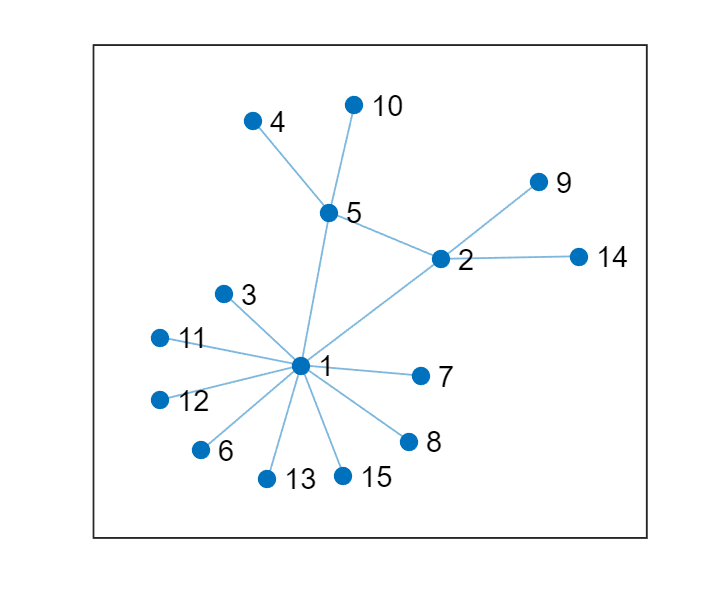

set(gcf,'Position',[100 100 260 220]);
plot(graph(bestGraph))

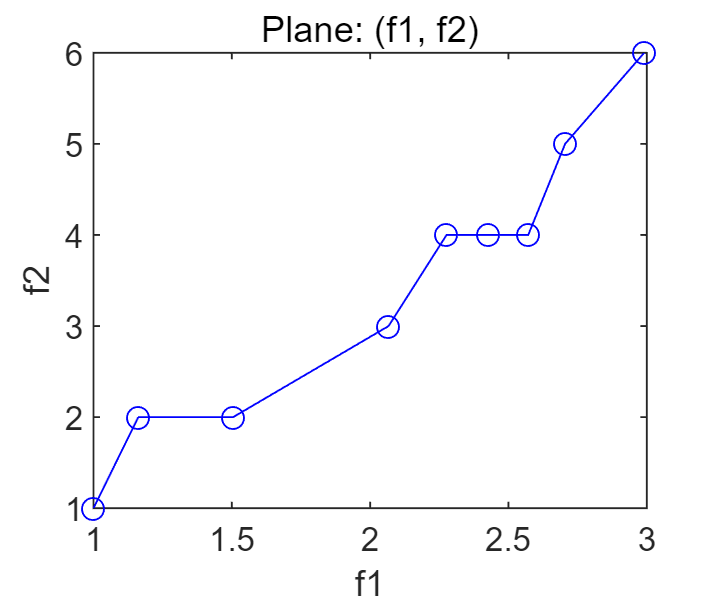

% Multi-Objective Evolutionary Algorithm
% Algorithm: NSGA-II 
% Minimize each of the three costs (f1, f2, f3)
% Return the 10 best solutions with their multi-fitness
[bestSolutions, multiFitValues] = MOEA(15, 0.3, 0.3);

% Calculate the inverse of multi-fitness to achieve the values of f1, f2, f3
f1 = ones(1, 10)./multiFitValues{1};
f2 = ones(1, 10)./multiFitValues{2};
f3 = ones(1, 10)./multiFitValues{3};

% Display the 10 best solutions, projected on the (f1, f2), (f1, f3), (f2, f3)
% Plane: (f1, f2)
set(gcf,'Position',[100 100 260 220]);
% Sort the values for connecting points into a line
[sortF1, sortIndexes] = sort(f1);
plot(sortF1, f2(sortIndexes), 'b-o');
title("Plane: (f1, f2)")
xlabel("f1")
ylabel("f2")

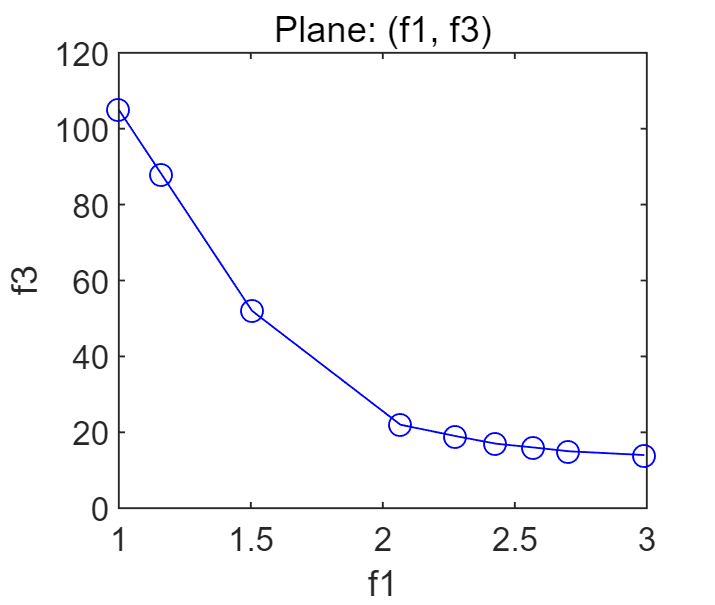

% axis([0, max(f1)+1, 0, max(f2)+1]);
% Plane: (f1, f3)
[sortF1, sortIndexes] = sort(f1);

plot(sortF1, f3(sortIndexes), 'b-o');
title("Plane: (f1, f3)")
xlabel("f1")
ylabel("f3")

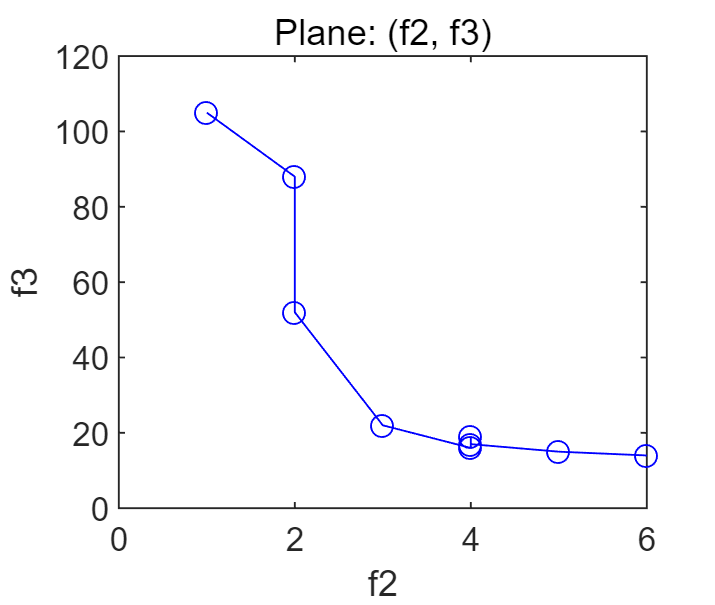

% Plane: (f2, f3)
[sortF2, sortIndexes] = sort(f2);
plot(sortF2, f3(sortIndexes), 'b-o');
title("Plane: (f2, f3)")
xlabel("f2")
ylabel("f3")

% List the table of f1, f2, f3 values of the 10 best solutions
for i = 1 : 10
    if i == 1
        fprintf("     f1        f2        f3")
    end
    fprintf("" + i + ": " + "%.4f,   %.4f,   %.4f\n", f1(i), f2(i), f3(i));
end

     f1        f2        f3

1: 1.0000,   1.0000,   105.0000
2: 2.9905,   6.0000,   14.0000
3: 1.0000,   1.0000,   105.0000
4: 1.1619,   2.0000,   88.0000
5: 2.0667,   3.0000,   22.0000
6: 2.5714,   4.0000,   16.0000
7: 1.5048,   2.0000,   52.0000
8: 2.2762,   4.0000,   19.0000
9: 2.7048,   5.0000,   15.0000
10: 2.4286,   4.0000,   17.0000


graphs = init_population(8, 150);

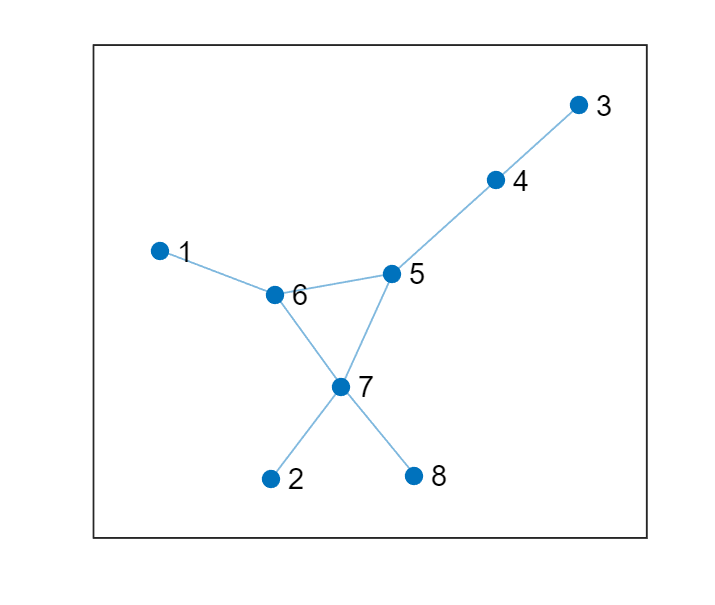

plot(graph(graphs{1}))

graphs = mutation(graphs, 0.3, 0.3);

ans = 3

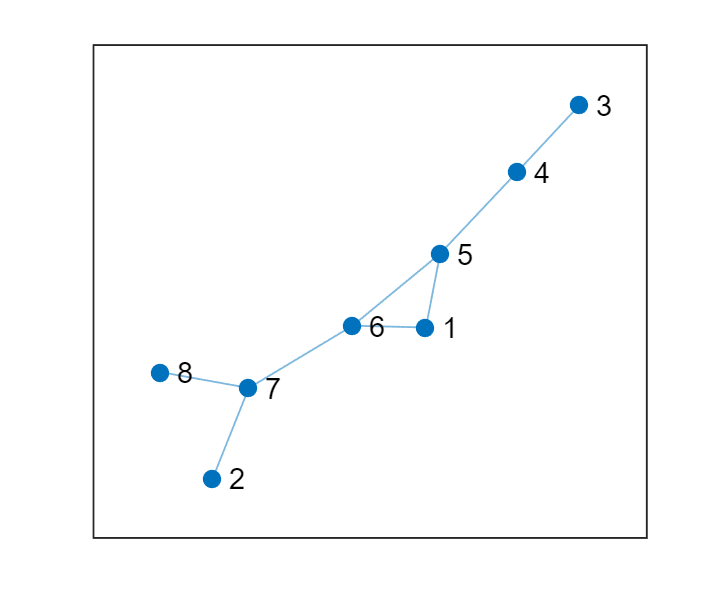

plot(graph(graphs{1}))

function newIndivs = mutation(parents, p1, p2)
    % Perform mutation operation on the network and return the mutated result
    parentSize = size(parents, 2);
    newIndivs = cell(1, parentSize);
    mutProb = [p1, p2 + p1, 1];
    for index = 1 : parentSize
        % Generate a random number to decide to use which mutation operators
        prob = rand();
        choice = find(prob <= mutProb);
        if index == 1
            choice(1)
        end
        switch choice(1)
            case 1
                % Add a link at a randomly chosen position
                newIndivs{1, index} = add_link(parents{1, index});
            case 2
                % Remove a randomly chosen link
                newIndivs{1, index} = remove_link(parents{1, index});
            case 3
                % Random rewiring
                newIndivs{1, index} = rewiring(parents{1, index});
        end
    end
end


function [G, rand1, rand2] = add_link(G)
    graphSize = size(G, 2);

    if check_fully_connected(G) == true
        return;
    else
        while true
            rand1 = randi(graphSize);
            rand2 = randi(graphSize);
            if rand1 ~= rand2 && G(rand1, rand2) == 0
                break;
            end
        end
        G(rand1, rand2) = 1;
        G(rand2, rand1) = 1;
    end
end


function [G, rand1, rand2] = remove_link(G)
    GCopy = G;
    verticeNum = size(G, 1);
    linkNum = cal_link_num(G);
    records = cell(1, linkNum);
    recIndex = 0;
    while recIndex < linkNum
        rand1 = randi(verticeNum);
        rand2 = randi(verticeNum);
        if (rand1 ~= rand2) && G(rand1, rand2) == 1 
            GCopy(rand1, rand2) = 0;
            GCopy(rand2, rand1) = 0;
            if check_connected(GCopy) == true
                G(rand1, rand2) = 0;
                G(rand2, rand1) = 0;
                return;
            else
                GCopy = G;
                [records, recIndex] = record_link(records, recIndex, rand1, rand2);
            end 
        end
    end
end


function G = rewiring(G)
    % Combine the adding link and removing link
    [G, rand1, rand2] = remove_link(G);
    verticeNum = size(G, 1);
    for index = 1 : verticeNum
        if (index ~= rand1) && (index ~= rand2)
            if G(rand1, index) == 0
                G(rand1, index) = 1;
                G(index, rand1) = 1;
                return;
            elseif G(rand2, index) == 0
                    G(rand2, index) = 1;
                    G(index, rand2) = 1;
                    return;
            end
        end
    end
end


function fullyConnected = check_fully_connected(G)
    % Check whether the graph is fully connected or not
    % return: 1/true(fully connected), 0/false(not fully connected)
    fullyConnected = true;
    for rowIndex = 1 : size(G, 1)
        for colIndex = rowIndex + 1 : size(G, 2)
            if G(rowIndex, colIndex) == 0
                % Value 0 means no link between these two nodes, so it is
                % not fully connected
                fullyConnected = false;
                return;
            end
        end
    end
end


function [records, recIndex] = record_link(records, recIndex, rand1, rand2)
    isExisted = false;
    for index = 1 : recIndex
        if all([rand1, rand2] == records{1, index}) == true
            isExisted = true;
            break;
        end
    end

    if isExisted == false
        recIndex = recIndex + 1;
        records{1, recIndex} = [rand1, rand2];
    end
end
